# 1110_Matlab上机实验

`1.`   

已知`V1 = [1, 5, 8, 10, 11]`，`V2 = [2, 4, 9 10]`

`1)` 求`V1`中所有元素之和，并确定`V1`中是否有元素`1`和`20`

`2)` 求`V2`中元素的最大值和最小值，并输出值对应的位置

`3)` 将`V1`中的前`3`个元素置为`0`

`4)` 将`V2`中所有元素缩小至原来的`1/2`

% 1
V1 = [1, 5, 8, 10, 11];
V2 = [2, 4, 9 10];
sum(V1)

ans = 35

ismember(1,V1)

ans = logical
   1


ismember(20,V1)

ans = logical
   0


% 2
max(V2)

ans = 10

min(V2)

ans = 2

find(V2==max(V2))

ans = 4

find(V2==min(V2))

ans = 1

% 3
V1(1:3) = 0

V1 =      0     0     0    10    11


% 4
V2 = V2/2

V2 =     1.0000    2.0000    4.5000    5.0000


**2.**

有如下两个矩阵：

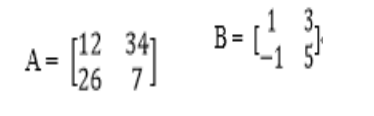

`1)` 求`A*``B`和`A.*``B`的值

`2)` 求`A``3`和`A.``3`的值

`3)` 求`A/B`和`B/A`的值

`4)` 输出`[A, B]`和`[B, A]`

A = [12,34;26,7]

A =     12    34
    26     7


B = [1,3;-1,5]

B =      1     3
    -1     5


A*B

ans =    -22   206
    19   113


A.*B

ans =     12   102
   -26    35


A^3

ans =        29132       39474
       30186       23327


A.^3

ans =         1728       39304
       17576         343


A/B

ans =    11.7500   -0.2500
   17.1250   -8.8750


B/A

ans =     0.0888   -0.0025
    0.1713   -0.1175


[A,B]

ans =     12    34     1     3
    26     7    -1     5


[B,A]

ans =      1     3    12    34
    -1     5    26     7


**3.** 

试在 `MATLAB`中输入下列矩阵，并使用`MATLAB`求解以下问题：

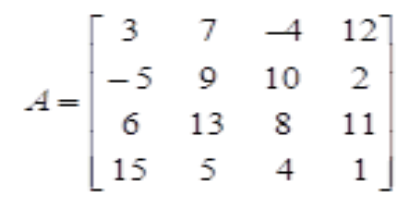                              

`1`） 试求`A^T, B=A+A*i, and B^T``;`

`2`）创建一个向量`V`，使`V`包含矩阵`A`中第二列的所有元素`.`

`3`）创建一个向量`W`，使`W`包含矩阵`A`中第二行的所有元素

`4`）创建一个`4x3`向量`B`，使`B`包含矩阵`A`中第二列至第四列中的所有元素

`5`）创建一个`3x4`向量`C`，使`C`包含矩阵`A`中第二行至第四行中的所有元素

`6`）创建一个`2x3`向量`D`，使`D`包含矩阵`A`中前两行和最后三列中的交集元素

`7`）求向量`V`和`W`的长度，并求矩阵`A, B, C ,D`的尺寸

A=[3,7,-4,12;
    -5,9,10,2;
    6,13,10,2;
    15,5,4,1]

A =      3     7    -4    12
    -5     9    10     2
     6    13    10     2
    15     5     4     1


A'

ans =      3    -5     6    15
     7     9    13     5
    -4    10    10     4
    12     2     2     1


B=A+A*2

B =      9    21   -12    36
   -15    27    30     6
    18    39    30     6
    45    15    12     3


B'

ans =      9   -15    18    45
    21    27    39    15
   -12    30    30    12
    36     6     6     3


V = A(:,2)

V =      7
     9
    13
     5


W = A(2,:)

W =     -5     9    10     2


B = A(:,2:4)

B =      7    -4    12
     9    10     2
    13    10     2
     5     4     1


C = A(2:4,:)

C =     -5     9    10     2
     6    13    10     2
    15     5     4     1


D = reshape(intersect(A(1:2,:),A(:,2:4)),2,3)

D =     -4     7    10
     2     9    12


length(V)

ans = 4

length(W)

ans = 4

size(A)

ans =      4     4


size(B)

ans =      4     3


size(C)

ans =      3     4


size(D)

ans =      2     3


**4.**

建立一个3´3的空矩阵C, 将C中第2列所有元素置为1, 向C中添加一行，该行元素值均为2, 输出当前矩阵C的规模.

m = ones(3,3)*nan

m =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


m(:,2)=1

m =    NaN     1   NaN
   NaN     1   NaN
   NaN     1   NaN


m=[m;[2,2,2]]

m =    NaN     1   NaN
   NaN     1   NaN
   NaN     1   NaN
     2     2     2


size(m)

ans =      4     3


**5.**

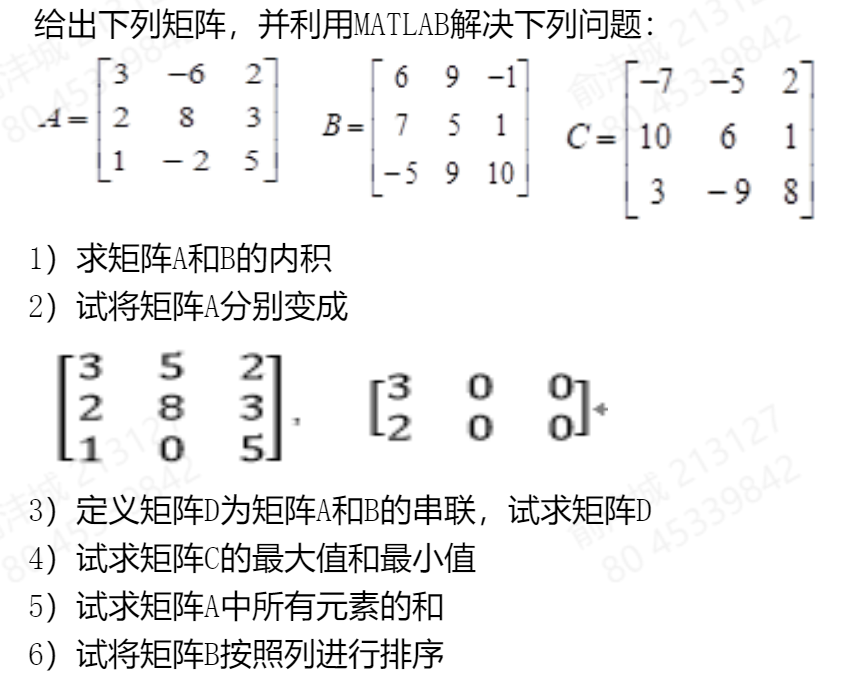

A=[3,-6,2;2,8,3;1,-2,5];
B=[6,9,-1;7,5,1;-5,9,10];
C=[-7,-5,2;10,6,1;3,-9,8];
% 1
A*B
% 2
A(:,2)=[5;8;0]
A(3,:)=[]
A(:,2:3)=0
% 3
A=[3,-6,2;2,8,3;1,-2,5];
D =[A,B]
% 4
max(max(C))
min(min(C))
% 5
sum(sum(A))
% 6
sort(B)

ans =    -34    15    11
    53    85    36
   -33    44    47


A =      3     5     2
     2     8     3
     1     0     5


A =      3     5     2
     2     8     3


A =      3     0     0
     2     0     0


D =      3    -6     2     6     9    -1
     2     8     3     7     5     1
     1    -2     5    -5     9    10


ans = 10

ans = -9

ans = 16

ans =     -5     5    -1
     6     9     1
     7     9    10


**6.**

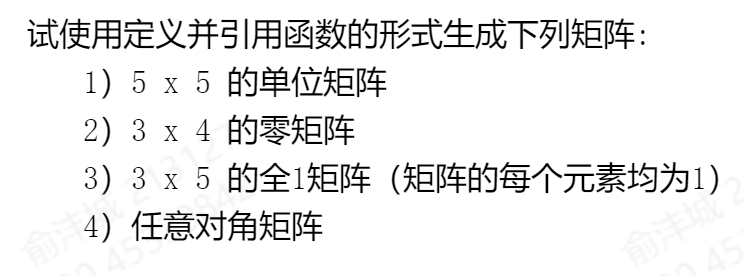

eye(5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


zeros(3,4)

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0


ones(3,5)

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


n=rand(1,3)

n =     0.9649    0.1576    0.9706


diag(n)

ans =     0.9649         0         0
         0    0.1576         0
         0         0    0.9706


**7.**

使用MATLAB创建一个100*5的矩阵，矩阵的每一行均为[1, 2, 3, 4, 5]

repmat(1:5,100,1)

ans =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


**8.**

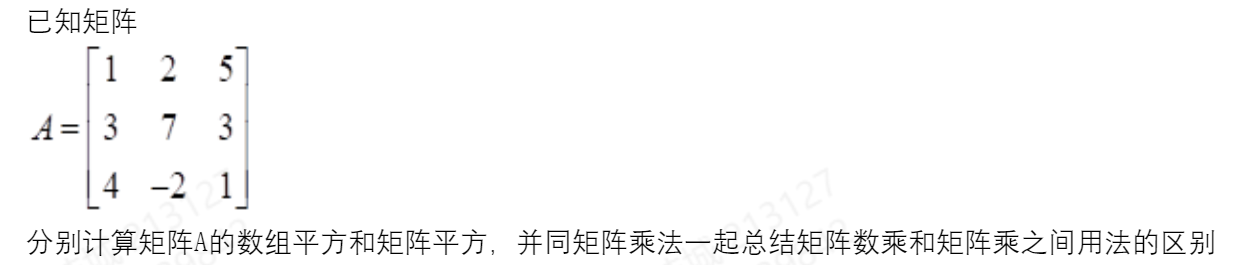

A=[1,2,5;3,7,3;4,-2,1]

A =      1     2     5
     3     7     3
     4    -2     1


A*A

ans =     27     6    16
    36    49    39
     2    -8    15


A.*A

ans =      1     4    25
     9    49     9
    16     4     1
